# Solar Sail BCR4BP - Gregory Zin

clc 
clear
close all


## Spacecraft Model

% idealize as single flat plate
SC.mass = 390 % 00; % kg, mass of Gateway 

SC = struct with fields:
    mass: 390


SC.area = 345;   % m^2, solar panel area
SC.R_diff = 0.5;
SC.R_spec = 0.5

SC = struct with fields:
      mass: 390
      area: 345
    R_diff: 0.500000000000000
    R_spec: 0.500000000000000


## Planetary Constants

% gravitational parameters [km^3 s^-2]
EARTH.mu =      398600.435507; 
MOON.mu =       4902.800118;
SUN.mu = 1.32712440041279419e11; 

% semi-major axis of Earth's orbit about Sun [km]
EARTH.a = 1.49598e8;
MOON.a =  384399.014; % relative to Earth


## BCP1 (Major): Earth-Moon Frame 

% rotating frame of Earth-Moon with Sun orbiting clockwise
% origin is B1, the Earth-Moon barycenter
% the Sun and B2 have circular orbits around B1

% Primary: Earth is located at [-BCP1.mu; 0; 0]
% Secondary: Moon is located at [1-BCP1.mu; 0; 0]
% Tertiary: Sun's position is time dependent

BCP1.mu = (MOON.mu)/(EARTH.mu + MOON.mu);
BCP1.LU = MOON.a; % km
BCP1.TU = sqrt(BCP1.LU^3/(EARTH.mu + MOON.mu)); % seconds

BCP1.a3 = EARTH.a/MOON.a; 
BCP1.mu3 = SUN.mu/(EARTH.mu + MOON.mu);
BCP1.n3 = ((1+BCP1.mu3)/BCP1.a3^3)^0.5 % 1/TU

BCP1 = struct with fields:
     mu: 0.012150584394710
     LU: 3.843990140000000e+05
     TU: 3.751888183305551e+05
     a3: 3.891737349773743e+02
    mu3: 3.289005597085648e+05
     n3: 0.074699497938179


## BCP2 (Minor): Sun-B1 Frame

% rotating frame of Sun-B1, where B1 is the Earth-Moon barycenter
% origin is B2, the barycenter of the Sun and B1
% the Sun and B1 have circular orbits around B2

% Primary: Sun is located at [-BCP2.mu; 0; 0]
% Secondary: B1 is located at [1-BCP2.mu; 0; 0]

BCP2.mu = (EARTH.mu + MOON.mu)/(SUN.mu + EARTH.mu + MOON.mu);
BCP2.LU = EARTH.a; % km
BCP2.TU = sqrt(BCP2.LU^3/(SUN.mu + EARTH.mu + MOON.mu)) %seconds

BCP2 = struct with fields:
    mu: 3.040423404760033e-06
    LU: 149598000
    TU: 5.022641767165042e+06



BCP2.TU * 2*pi / (86400)

ans =      3.652568166050684e+02


## NRHO in BCR4BP

% initial condition for 9:2 NRHO in BCR4BP
% Y0 = [0.987442481206598;
%     0;
%     0.008702844515714;
%     0;
%     1.640997906790213;
%     0;
%     0];

% location of departure along reference NRHO
% (index 1201, found from script BR4BP_EscapeTrajectory)
Yd = [1.016199666777148;
    0.043953600688565;
    -0.114729547537933;
    0.069113173822688;
    -0.029738753389694;
    -0.284151852739576;
    -7.205475689979612];


% delta-V magnitude in m/s
A = 1 % m/s

A =      1



% convert to nondimensional units
a = A*BCP1.TU/(BCP1.LU*1000)

a =      9.760400122424745e-04



% deltaV manuever applied in x direction
Y0 = Yd + [0; 0; 0; a; 0; 0; 0]

Y0 =    1.016199666777148
   0.043953600688565
  -0.114729547537933
   0.070089213834930
  -0.029738753389694
  -0.284151852739576
  -7.205475689979612


## Propagate without SRP

% initial and final time
t0 = 0

t0 =      0


tf = 500*pi

tf =      1.570796326794896e+03



% integration tolerances
options = odeset('RelTol', 1e-12, 'AbsTol', 1e-16);

% regular BCR4BP dynamics, no SRP
% [t_NOS,Y_NOS] = ode113(@(t,Y) BCR4BP(t,Y,BCP1), [t0 tf], Y0, options);
[t_NOS,Y_NOS] = ode78e(@(t,Y) BCR4BP(t,Y,BCP1), t0, tf, Y0, 10^-16);


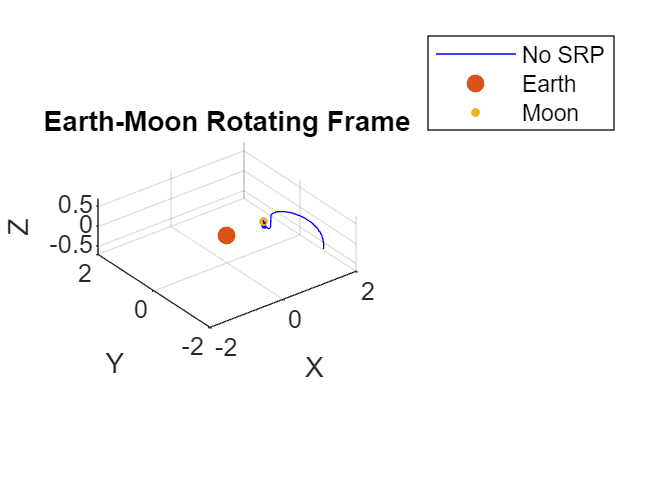


figure
plt(Y_NOS,4,'b');
hold on
plot3(-BCP1.mu,0,0,'.','MarkerSize',20)
plot3(1-BCP1.mu,0,0,'.','MarkerSize',10)
title('Earth-Moon Rotating Frame')
legend('No SRP','Earth','Moon')
axis([-2 2 -2 2])

## Propagate with SRP

% constant orientation with respect to Sun in RTN frame
U = [pi/4, 0] % radians

U =    0.785398163397448                   0


% U = [0,0] % radians

% initial and final time
t0 = 0

t0 =      0


tf = 10*pi

tf =   31.415926535897931



% BCR4BP dynamics with solar radiation pressure
% [t_SRP,Y_SRP] = ode113(@(t,Y) BCR4BP_SRP(t,Y,U,BCP1,BCP2,SC), [t0 tf], Y0, options);
[t_SRP,Y_SRP] = ode78e(@(t,Y) BCR4BP_SRP(t,Y,U,BCP1,BCP2,SC), t0, tf, Y0, 10^-16);


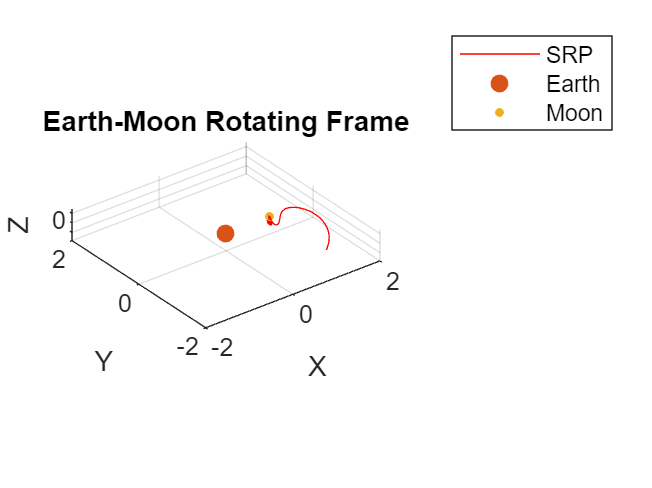


figure
plt(Y_SRP,4,'r');
hold on
plot3(-BCP1.mu,0,0,'.','MarkerSize',20)
plot3(1-BCP1.mu,0,0,'.','MarkerSize',10)
title('Earth-Moon Rotating Frame')
legend('SRP','Earth','Moon')
axis([-2 2 -2 2])

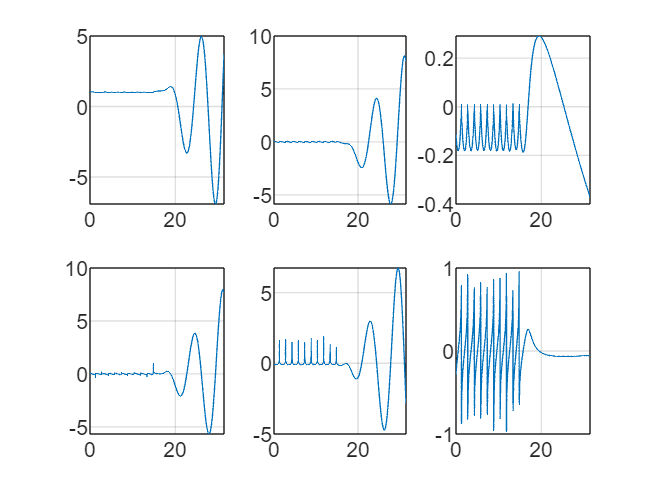


figure
subplot(2,3,1)
plot(t_SRP,Y_SRP(:,1))
grid on

subplot(2,3,2)
plot(t_SRP,Y_SRP(:,2))
grid on

subplot(2,3,3)
plot(t_SRP,Y_SRP(:,3))
grid on

subplot(2,3,4)
plot(t_SRP,Y_SRP(:,4))
grid on

subplot(2,3,5)
plot(t_SRP,Y_SRP(:,5))
grid on

subplot(2,3,6)
plot(t_SRP,Y_SRP(:,6))
grid on

## Convert to BCP2 frame

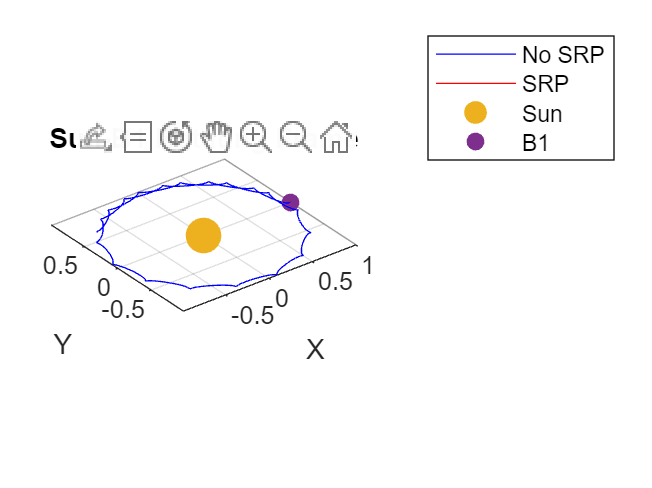

% use BCP1toBCP2 function
[t_NOS2,Y_NOS2] = BCP1toBCP2(t_NOS,Y_NOS,BCP1,BCP2);
[t_SRP2,Y_SRP2] = BCP1toBCP2(t_SRP,Y_SRP,BCP1,BCP2);

figure
plt(Y_NOS2,4,'b');
hold on
plt(Y_SRP2,4,'r');
plot3(-BCP2.mu, 0, 0, '.', 'MarkerSize', 40)
plot3(1-BCP2.mu, 0, 0, '.', 'MarkerSize', 20)
axis equal
grid on
legend('No SRP','SRP','Sun','B1')
title('Sun-B1 Rotating Frame')

## Convert to Sun Centered Inertial Frame

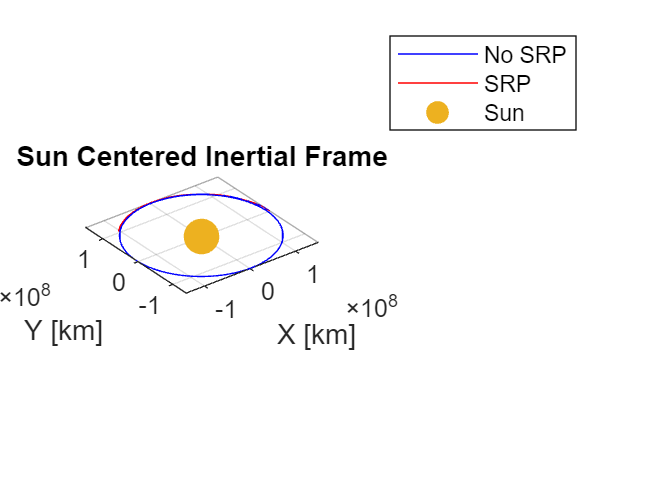

% use rot2inert function
[T_NOSI,Y_NOSI] = rot2inert(t_NOS2,Y_NOS2,BCP2.mu,BCP2.LU,BCP2.TU,1);
[T_SRPI,Y_SRPI] = rot2inert(t_SRP2,Y_SRP2,BCP2.mu,BCP2.LU,BCP2.TU,1);

figure
plot3(Y_NOSI(:,1),Y_NOSI(:,2),Y_NOSI(:,3),'b')
hold on
plot3(Y_SRPI(:,1),Y_SRPI(:,2),Y_SRPI(:,3),'r')
plot3(0, 0, 0, '.', 'MarkerSize', 40)
grid on
axis equal
xlabel('X [km]')
ylabel('Y [km]')
zlabel('Z [km]')
legend('No SRP','SRP','Sun')
title('Sun Centered Inertial Frame')

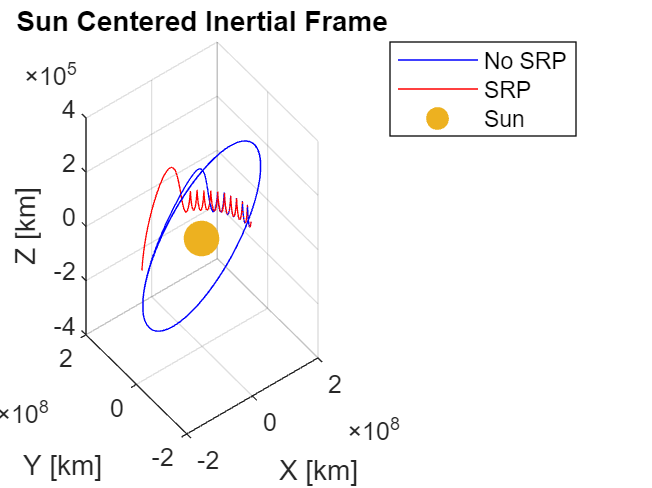


figure
plot3(Y_NOSI(:,1),Y_NOSI(:,2),Y_NOSI(:,3),'b')
hold on
plot3(Y_SRPI(:,1),Y_SRPI(:,2),Y_SRPI(:,3),'r')
plot3(0, 0, 0, '.', 'MarkerSize', 40)
grid on
% axis equal
xlabel('X [km]')
ylabel('Y [km]')
zlabel('Z [km]')
legend('No SRP','SRP','Sun')
title('Sun Centered Inertial Frame')

## Look at Distance to Sun

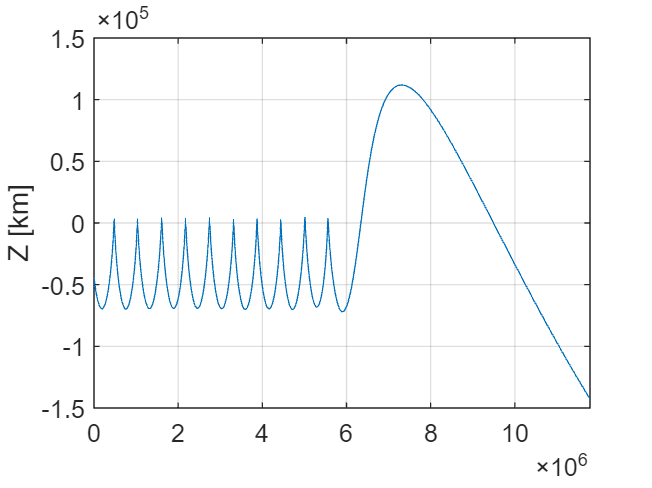

figure
plot(T_SRPI,Y_SRPI(:,3))
grid on
ylabel('Z [km]')

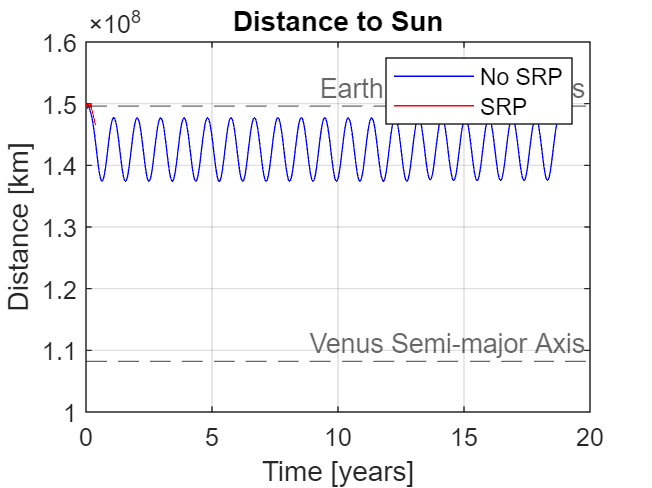


% figure
% plot(t_SRP,Y_SRP(:,3))
% grid on

figure
plot(T_NOSI/(2*pi*BCP2.TU),vecnorm(Y_NOSI(:,1:3),2,2),'b')
hold on
plot(T_SRPI/(2*pi*BCP2.TU),vecnorm(Y_SRPI(:,1:3),2,2),'r')
yline(BCP2.LU,'--','Earth Semi-major Axis')
yline(1.08209e8,'--','Venus Semi-major Axis')
legend('No SRP','SRP')
xlabel('Time [years]')
ylabel('Distance [km]')
grid on
title('Distance to Sun')